%It computes time-in-comfort, longest discomfort streak, and visualizes results.
% It also recommends an HVAC adjustment strategy with a what-if analysis.


%{
ES115 Building HVAC Comfort analysis
 originally from Final module Project Bank - 02/02/2026
Author: Gracy Sylvestre
Version: 2.0
Date: 2026-04-25
State the problem (Purpose):
 This script analyzes indoor temperature trends and evaluates comfort levels.





Describe input values (Knowns)and required output (Unknowns) 
    Input: - Linear and Piecewise function
          - usage range
    Output:
        - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
       - table of usage values and corresponding bills for both plans
      - intersection point where both bills cost the same
      - plan reccomendations specific to usage value of choice
     
  Engineering Workflow and Algarithems:
   - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding

MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
    -  if/else/end 
    - plot function
    - table function
    - fprintf
 %}

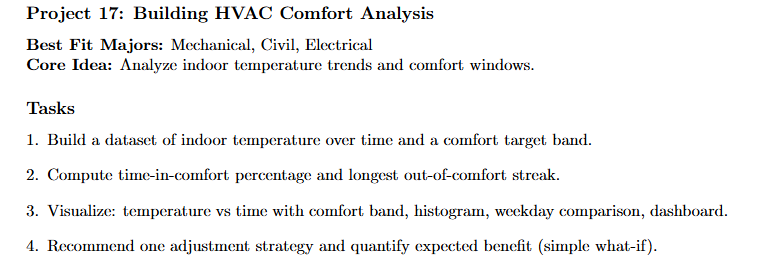


clc; clear; close all; % Clear workspace

%user input


NDays = input('Enter number of days to simulate (e.g., 7): '); %entr simulation # of days

% comfort temp range
mintemp = input('Enter minimum comfortable temperature (°F): '); %enter min comfort temp
maxtemp = input('Enter maximum comfortable temperature (°F): '); %enter max comfort temp

%only accept valid inputs
if mintemp >= maxtemp
    error('Minimum comfort temperature must be less than maximum.'); %if min temp is greater than max temp then invalid
end

## Task 1: Build a dataset of indoor temperature over time and a comfort target band

% form data set

%time vector for hourly data
Hday = 24; %# of hours in a day
Htotal = NDays * Hday; % simulation hours in total
t = 1:Htotal; % array for time

% build indoor temperature data (sin wave)

% variation for dailt temp

tempi = 70; %base level indoor temp
amp = 5; %flunctuation for daily pattern (amplitude)
noise = randn(1, Htotal); % Random noise

tempf = tempi + amp * sin(2*pi*t/24) + noise; %establish temp over time

## Task 2: Compute time-in-comfort percentage and longest out-of-comfort streak.

%analyze comfort


inComfort = (tempf >= mintemp) & (tempf <= maxtemp); %determine if each time step falls within comfort range


tInComfort = (sum(inComfort) / Htotal) * 100; %determine percentage of time in comfort

% search for longest out-of-comfort streak
maxstreak = 0; % establish max streak for out of comfort periods

streaknow = 0; %streak counter

for a = 1:Htotal 
    if ~inComfort(a) % if in out of comfort period
        streaknow = streaknow + 1;  %count up on streak counter
        if streaknow > maxstreak % if streak counter is greater than max streak
            maxstreak = streaknow; % Update max streak to reflect the same value current streak
        end
    else   %otherwise
        streaknow = 0; % Reset streak if back in comfort
    end
end

## Task 3: Visualize: temperature vs time with comfort band, histogram, weekday comparison, dashboard.

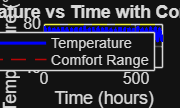

%visuals

% Plot temp vs time with comfort band
figure;  %establish new figure
plot(t, tempf, 'b', 'LineWidth', 1.5); hold on; %plot figure in blue
yline(mintemp, 'r--', 'Min Comfort'); %plot horizontal red dashed line marking the min comfort temp
yline(maxtemp, 'y--', 'Max Comfort'); %plot horizontal yellow dashed line marking the max comfort temp
xlabel('Time (hours)');  %establish title for horizontal axis
ylabel('Temperature (°F)'); %establish title for vertical axis
title('Temperature vs Time with Comfort Band'); %establish title for horizontal axis
legend('Temperature', 'Comfort Range', 'Location','northeast'); %estavlish legend with all variables(top right corner)
grid on; 

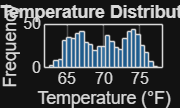


% create histogram for temp distribution
figure; %create new figure
histogram(tempf, 25); %form histogram with 25 bars for comparison
xlabel('Temperature (°F)'); %label horizontal axis
ylabel('Frequency'); %labvel vertical axis
title('Temperature Distribution'); %title the plotted graph
grid on;

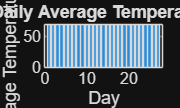



% Weekday comparison 

avgday = zeros(1, NDays); % establish array for average per day

for d = 1:NDays    %loop for daily average
    idki = (d-1)*24 + 1;
    idxf = d*24;
    avgday(d) = mean(tempf(idki:idxf));
end

figure; %new figure
bar(1:NDays, avgday); %plot bar graph 
xlabel('Day'); %title the horizontal axis
ylabel('Average Temperature (°F)'); %title the vertical axis
title('Daily Average Temperature'); %title the plot
grid on; 



%dashboard
fprintf('\n    HVAC Comfort Analysis Summary!    \n'); %print title of dashboard summary


    HVAC Comfort Analysis Summary!    


fprintf('Total Hours: %d\n', Htotal); %print total about of simulation hours used

Total Hours: 648


fprintf('Time in Comfort: %.2f%%\n', tInComfort); %print time in comfort percentage

Time in Comfort: 100.00%


fprintf('Longest Out-of-Comfort Streak: %d hours\n', maxstreak); %print max streak removed from comfort

Longest Out-of-Comfort Streak: 0 hours


## Task 4: Recommend one adjustment strategy and quantify expected benefit (simple what-if)

%what if recommendations

% adjustment strategy: reduce tempfluctuations to produce better HVAC control
amp2 = amp * 0.6; % Reduce fluctuation by 40%


adjTemp = tempi + amp2 * sin(2*pi*t/24) + noise; % simulate adjusted temperature

% Recalculate comfort

inComfort2 = (adjTemp >= mintemp) & (adjTemp <= maxtemp); %calculate if each new time step falls within comfort range

tincomfort2 = (sum(inComfort2) / Htotal) * 100; %redetermine percentage of time in comfort

% print improvement
fprintf('\n Recommended Strategy \n'); %display reccomendation title


 Recommended Strategy 


fprintf('Reduce temperature fluctuation via improved HVAC control.\n'); %display strategy

Reduce temperature fluctuation via improved HVAC control.


fprintf('Expected Comfort Increase: %.2f%% -> %.2f%%\n', ...
    tInComfort, tincomfort2); %display new calculation results

Expected Comfort Increase: 100.00% -> 100.00%




%testing with different inputs

testTemps = [65, 72, 78]; % sample test values

fprintf('\n Temperatre Test Cases \n'); %display title of sample case section


 Temperatre Test Cases 


for a = 1:length(testTemps)
    if testTemps(a) >= mintemp && testTemps(a) <= maxtemp 
% if the results of the test temps are greater of equal to the min temp yet less than or equal to the max temp
        fprintf('Temperature %.1f°F is within comfort.\n', testTemps(a)); %display that results fall within comfort range
    else %otherwise
        fprintf('Temperature %.1f°F is OUT of comfort.\n', testTemps(a)); %display that temp falls put of comfort range
    end
end

Temperature 65.0°F is within comfort.
Temperature 72.0°F is within comfort.
Temperature 78.0°F is within comfort.


%{ 
Reflection After Completing the Project: 

- What did you learn?
 Throughout my completion of this project, ... 
 
  - What could be done differently?
many features among this project couldv'e been done differently such as ... 
   
- Rate the project (1 - 10) (1 - represents simple and 10 represents difficult) 
   Rate : ...
%}